clc

clear
imaqreset
close all;

webcam_list = webcamlist

webcam_list = 3×1 cell array
    {'Microsoft® LifeCam Cinema(TM)'}
    {'FaceTime HD Camera (Built-in)'}
    {'Snap Camera'                  }


imaqhwinfo

ans = struct with fields:
    InstalledAdaptors: {'macvideo'}
        MATLABVersion: '9.13 (R2022b)'
          ToolboxName: 'Image Acquisition Toolbox'
       ToolboxVersion: '6.7 (R2022b)'


imaqhwinfo('macvideo',1)

ans = struct with fields:
             DefaultFormat: 'YCbCr422_1280x720'
       DeviceFileSupported: 0
                DeviceName: 'Microsoft\256 LifeCam Cinema(TM)'
                  DeviceID: 1
     VideoInputConstructor: 'videoinput('macvideo', 1)'
    VideoDeviceConstructor: 'imaq.VideoDevice('macvideo', 1)'
          SupportedFormats: {'YCbCr422_1280x720'  'YCbCr422_192x144'  'YCbCr422_320x240'  'YCbCr422_352x288'  'YCbCr422_480x360'  'YCbCr422_960x540'}


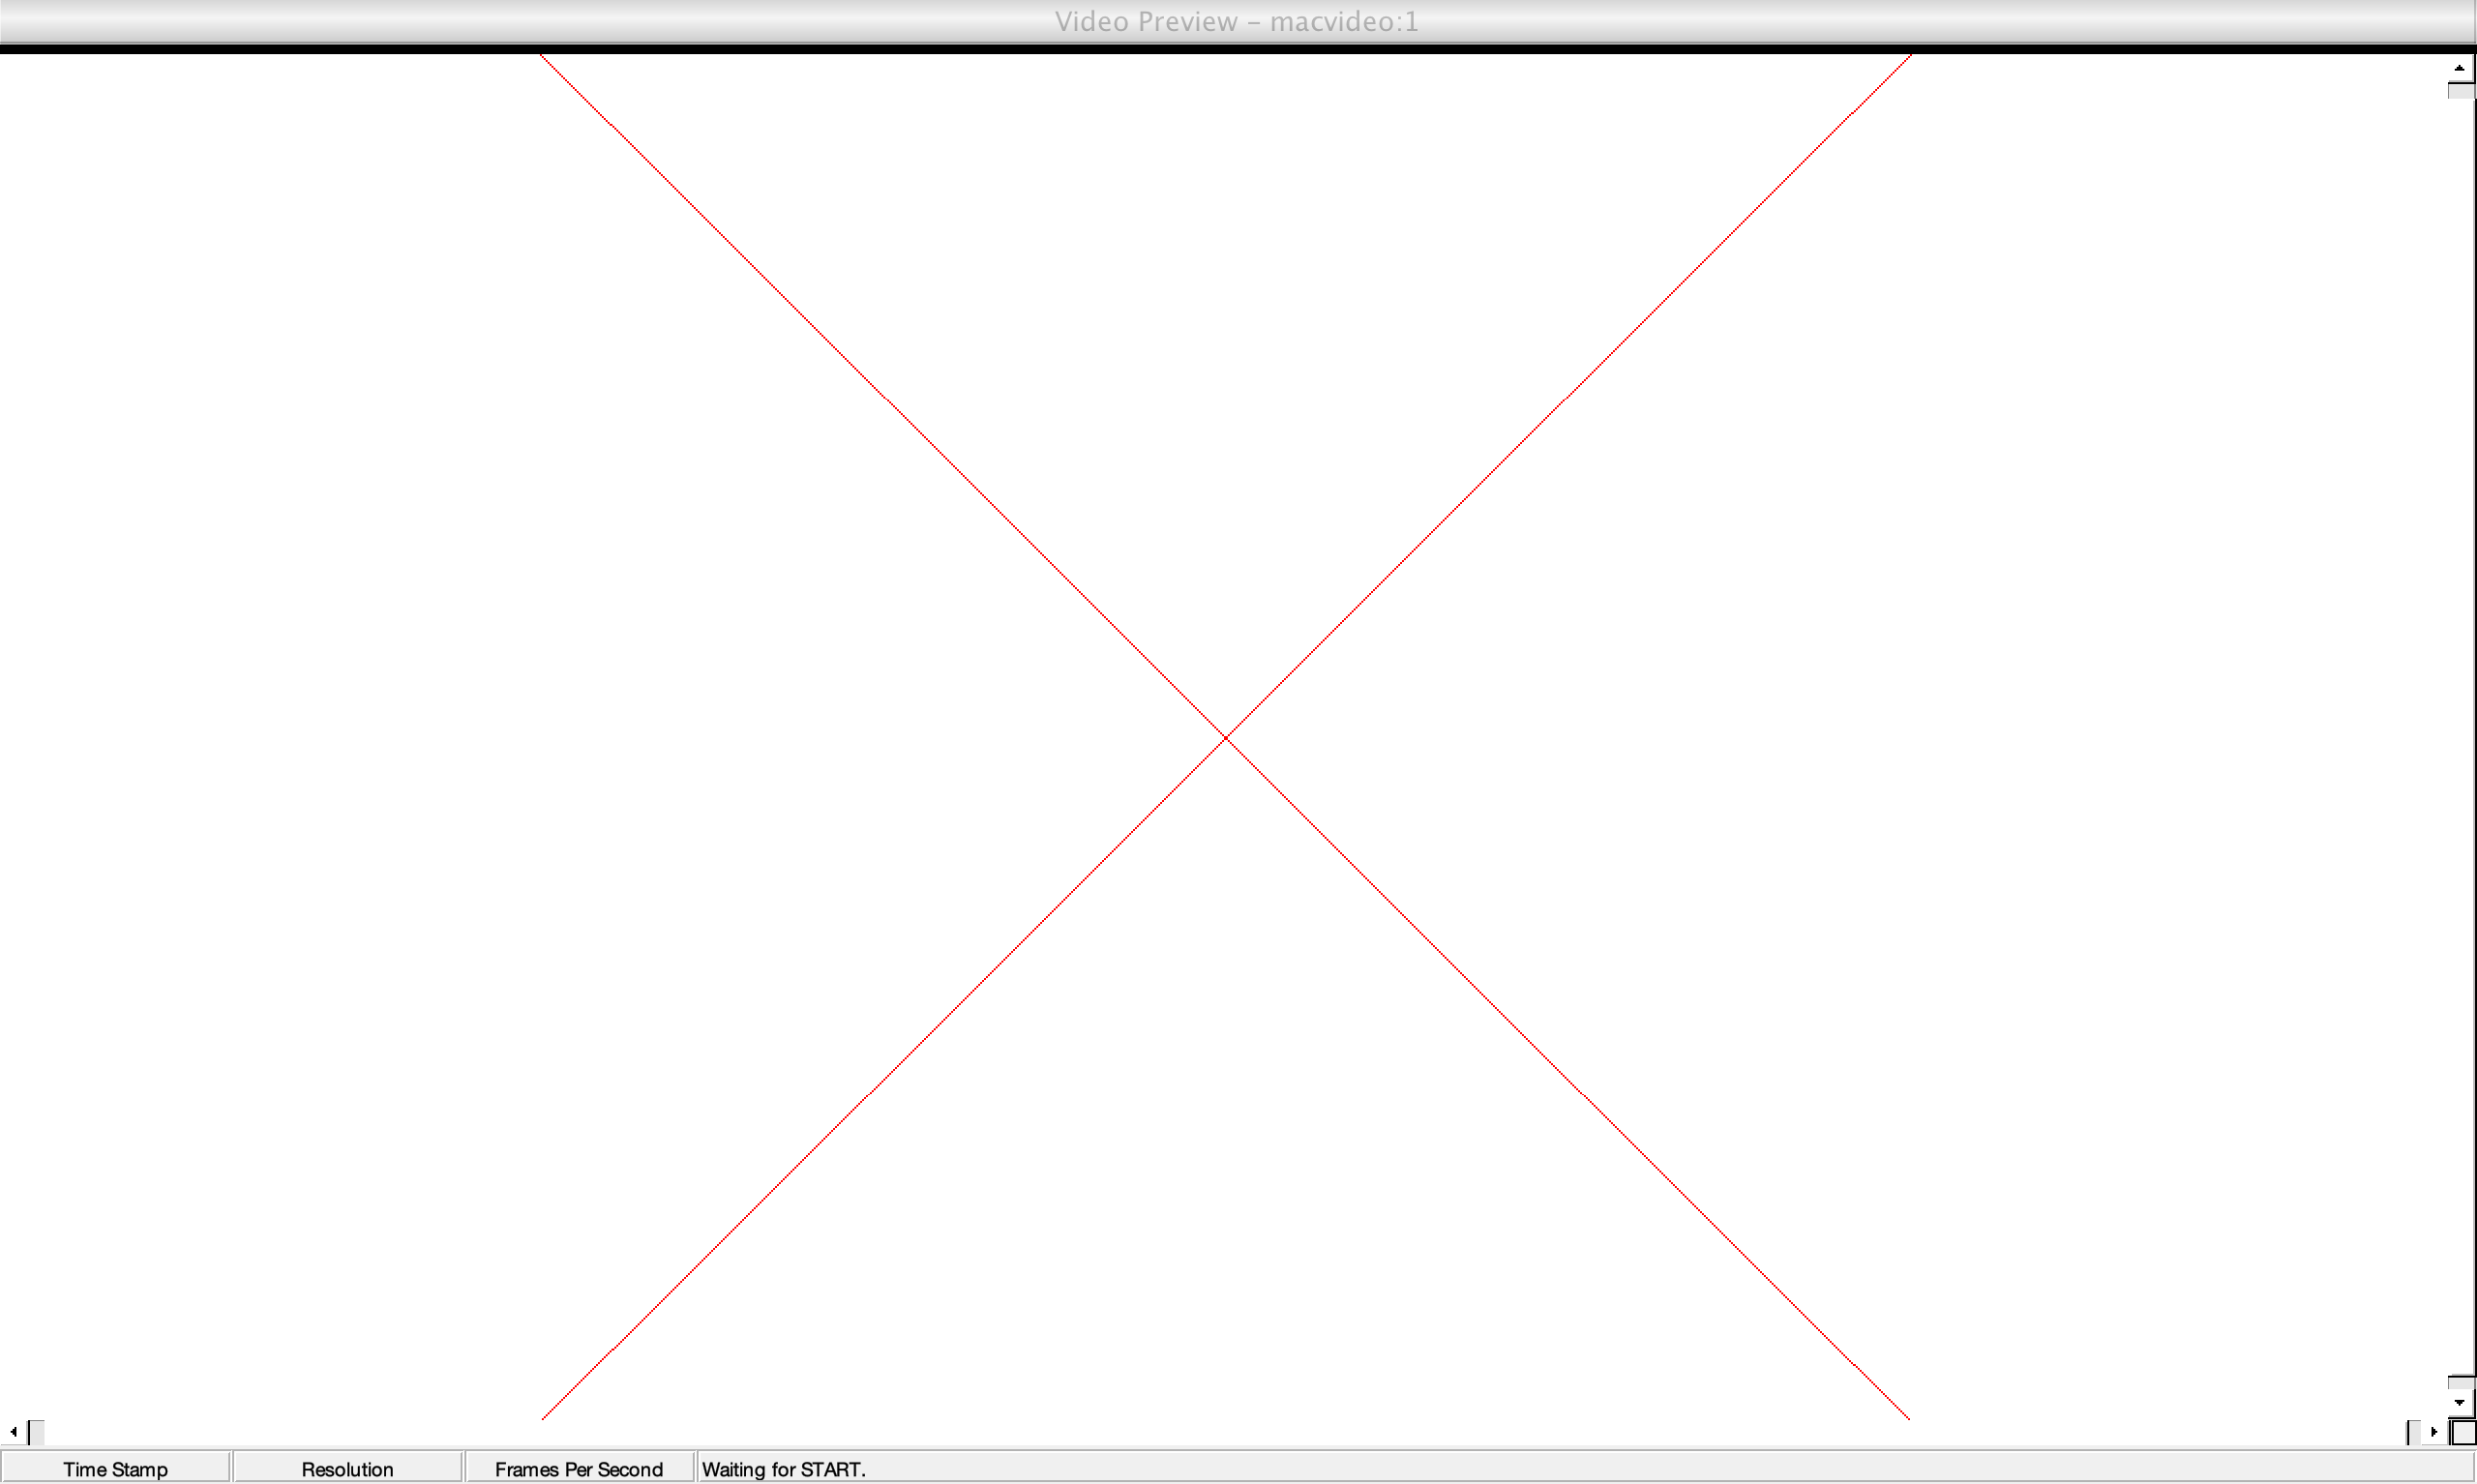

vid = videoinput('macvideo',1);
start(vid);
% data = getdata(vid,1)
% imshow(data);
preview(vid);

closepreview(vid);
stop(vid);

get(vid)

% Set video input object properties for this application.
vid.TriggerRepeat = Inf;
vid.FrameGrabInterval = 5;

% Set value of a video source object property.
vid_src = getselectedsource(vid);
vid_src.Tag = 'motion detection setup';

% Create a figure window.
close all;

figure() 
set(gcf,'Visible','on')

% Start acquiring frames.
start(vid);
pause(1);
% 
show = 1;
% Calculate difference image and display it.
% while(vid.FramesAvailable > 0)
while show == 1
    disp(vid.FramesAvailable)
    if vid.FramesAvailable > 0
        data = getdata(vid,1); 
        img = ycbcr2rgb(data);
        imshow(img);
        hold on
        hsv_img = rgb2hsv(img);
        lower_red = [110,150,100];
        upper_red = [255,255,255];
        red_mask = mask_img(hsv_img,lower_red,upper_red);
        lower_yellow = [20,100,100];
        upper_yellow = [80,255,255];
        yellow_mask = mask_img(hsv_img,lower_yellow,upper_yellow);
        lower_green = [80,80,50];
        upper_green = [150,180,150];
        green_mask = mask_img(hsv_img,lower_green,upper_green);
        
        largest_red = smooth_image(red_mask);
        largest_green = smooth_image(green_mask);
        largest_yellow = smooth_image(yellow_mask);
        [rb, hr] = find_contour(largest_red,'red');
        [yb, hb] = find_contour(largest_yellow,'yellow');
        [gb, hg] = find_contour(largest_green,'green');

    bounds = {rb;yb;gb};
    colors = ['r' 'y' 'g']
    texts = ['red','yellow','green'];
    h = [hr;hb;hg];
    for i=1:3
        boundary = cell2mat(bounds(i));
        plot(boundary(:,2), boundary(:,1),colors(i),'LineWidth',2);
        set(h(i),'Color',colors(i),'FontSize',20,'FontWeight','bold');
    end

    else
        hold on
    
   
    end
    drawnow     % update figure window
    hold off
end

     6



colors = 'ryg'

     7



colors = 'ryg'

     8



colors = 'ryg'

     8



colors = 'ryg'

     9



colors = 'ryg'

     9



colors = 'ryg'

    10



colors = 'ryg'

    10



colors = 'ryg'

    11



colors = 'ryg'

    11



colors = 'ryg'

    12



colors = 'ryg'

    12



colors = 'ryg'

    13



colors = 'ryg'

    13



colors = 'ryg'

    14



colors = 'ryg'

    14



colors = 'ryg'

    15



colors = 'ryg'

    15



colors = 'ryg'

    16



colors = 'ryg'

    16



colors = 'ryg'

    17



colors = 'ryg'

    17



colors = 'ryg'

    18



colors = 'ryg'

    18



colors = 'ryg'

    19



colors = 'ryg'

    19



colors = 'ryg'

    20



colors = 'ryg'

    20



colors = 'ryg'

    21



colors = 'ryg'

    21



colors = 'ryg'

    21



colors = 'ryg'

    22



colors = 'ryg'

    23



colors = 'ryg'

    23



colors = 'ryg'

    24



colors = 'ryg'

    24



colors = 'ryg'

    25



colors = 'ryg'

    25



colors = 'ryg'

    25



colors = 'ryg'

    26



colors = 'ryg'

    26



colors = 'ryg'

    27



colors = 'ryg'

    27



colors = 'ryg'

    27



colors = 'ryg'

    28



colors = 'ryg'

    28



colors = 'ryg'

    29



colors = 'ryg'

    29



colors = 'ryg'

    29



colors = 'ryg'

    30



colors = 'ryg'

    30



colors = 'ryg'

    31



colors = 'ryg'

    31



colors = 'ryg'

    32



colors = 'ryg'

    32



colors = 'ryg'

    32



colors = 'ryg'

    33



colors = 'ryg'

    34



colors = 'ryg'

    34



colors = 'ryg'

    35



colors = 'ryg'

    35



colors = 'ryg'

    36



colors = 'ryg'

    36



colors = 'ryg'

    37



colors = 'ryg'

    37



colors = 'ryg'

    38



colors = 'ryg'

    38



colors = 'ryg'

    39



colors = 'ryg'

    39



colors = 'ryg'

    39



colors = 'ryg'

    40



colors = 'ryg'

    40



colors = 'ryg'

    41



colors = 'ryg'

    41



colors = 'ryg'

    42



colors = 'ryg'

    42



colors = 'ryg'

    42



colors = 'ryg'

    43



colors = 'ryg'

    43



colors = 'ryg'

    44



colors = 'ryg'

    44



colors = 'ryg'

    45



colors = 'ryg'

    45



colors = 'ryg'

    46



colors = 'ryg'

    46



colors = 'ryg'

    47



colors = 'ryg'

    47



colors = 'ryg'

    47



colors = 'ryg'

    48



colors = 'ryg'

    48



colors = 'ryg'

    49



colors = 'ryg'

    49



colors = 'ryg'

    50



colors = 'ryg'

    50



colors = 'ryg'

    51



colors = 'ryg'

    51



colors = 'ryg'

    51



colors = 'ryg'

    52



colors = 'ryg'

    52



colors = 'ryg'

    53



colors = 'ryg'

    53



colors = 'ryg'

    54



colors = 'ryg'

    54



colors = 'ryg'

    55



colors = 'ryg'

    55



colors = 'ryg'

    56



colors = 'ryg'

    56



colors = 'ryg'

    57



colors = 'ryg'

    57



colors = 'ryg'

    57



colors = 'ryg'

    58



colors = 'ryg'

    58



colors = 'ryg'

    59



colors = 'ryg'

    59



colors = 'ryg'

    60



colors = 'ryg'

    60



colors = 'ryg'

    61



colors = 'ryg'

    61



colors = 'ryg'

    62



colors = 'ryg'

    62



colors = 'ryg'

    62



colors = 'ryg'

    63



colors = 'ryg'

    63



colors = 'ryg'

    64



colors = 'ryg'

    64



colors = 'ryg'

    65



colors = 'ryg'

    65



colors = 'ryg'

    65



colors = 'ryg'

    66



colors = 'ryg'

    66



colors = 'ryg'

    67



colors = 'ryg'

    67



colors = 'ryg'

    68



colors = 'ryg'

    68



colors = 'ryg'

    68



colors = 'ryg'

    69



colors = 'ryg'

    69



colors = 'ryg'

    70



colors = 'ryg'

    70



colors = 'ryg'

    70



colors = 'ryg'

    71



colors = 'ryg'

    71



colors = 'ryg'

    72



colors = 'ryg'

    72



colors = 'ryg'

    73



colors = 'ryg'

    73



colors = 'ryg'

    74



colors = 'ryg'

    74



colors = 'ryg'

    75



colors = 'ryg'

    75



colors = 'ryg'

    76



colors = 'ryg'

    76



disp('ended')

stop(vid)


delete(vid)
clear
close(gcf)

img = ycbcr2rgb(data);
imshow(img);

function [boundary, h] = find_contour(area_img,txt)
    B = bwboundaries(area_img);
    boundary = B{1};
    rndRow = length(boundary);
    col = boundary(rndRow,2);
    row = boundary(rndRow,1);
    h = text(col+1, row-1,txt);
end

function mask = mask_img(hsv_img,lower,upper)
    lower = lower/256;
    upper = upper/256;
    h = hsv_img(:,:,1);
    s = hsv_img(:,:,2);
    v = hsv_img(:,:,3);
    h_mask = h >= lower(1) & h <= upper(1);
    s_mask = s >= lower(2) & s <= upper(2);
    v_mask = v >= lower(3) & v <= upper(3);
    mask = h_mask & s_mask & v_mask;
end

function largest_area = smooth_image(mask)
    %dilation
    se = strel('disk',5);
    smooth = imdilate(mask,se);
    im_fill = imfill(smooth, 'holes');

    % remove parts that are smaller than 500 pixels
    filtered = bwareaopen(im_fill,500);
%     imshow(filtered);
    % find largest area
    s = regionprops(filtered, 'Area', 'PixelList');
    
    [~,idx] = max([s.Area]);

    Indices = s(idx).PixelList;
    largest_area = false(size(filtered));
 
    for i = 1:length(Indices)

        largest_area(Indices(i,2),Indices(i,1)) = 1;
    end
    
    
end